%% =========================================================================
%  E23 EXAM SOLUTIONS - Using EM Helper Toolkit
%  =========================================================================
%  This script demonstrates how to use the consolidated helper functions
%  to solve the Winter 2023 Electromagnetics exam.
%
%  Add the helpers to your path first:
addpath('C:\Users\Mads2\DTU\3.semester\Electromagnetics\Helpers');
%  =========================================================================

clear; clc;

%% Constants
c0 = 2.99792458e8;      % Speed of light [m/s]
eps0 = 8.85418781762e-12; % Permittivity of free space
mu0 = 1.25663706144e-6;   % Permeability of free space
eta0 = sqrt(mu0/eps0);    % ≈ 377 Ω




## Q4 — VSWR for Γ = -j/3

Gamma = -1j/3;

% Use TLine to get VSWR from Gamma
% First convert Gamma to Z, then analyze
r = TLine('Z', 50, Gamma);  % Gives us Z from Gamma


=== Impedance from Gamma ===
  Z0 = 50.00 Ohm
  Gamma = 0.0000 -0.3333j
  |Gamma| = 0.3333, angle = -90.00 deg
  ----------------------------
  Z = 40.0000 -30.0000j Ohm



% Or calculate directly:
VSWR_manual = (1 + abs(Gamma)) / (1 - abs(Gamma));
fprintf('Direct calculation: VSWR = %.4f\n', VSWR_manual);

Direct calculation: VSWR = 2.0000


## Q5 — Power Reflected When |Γ| = 0.3

Gamma_mag = 0.3;
P_reflected = Gamma_mag^2;
fprintf('Reflected power = |Γ|² = %.2f = %.0f%%\n', P_reflected, P_reflected*100);

Reflected power = |Γ|² = 0.09 = 9%


## Q6 — Ideal Short Circuit reflection coefficient

ZL_short = 0;
Z0 = 50;  % arbitrary
r = TLine('Gamma', Z0, ZL_short);


=== Reflection Coefficient ===
  Z0 = 50.00 Ohm
  Z  = 0.0000 +0.0000j Ohm
  ------------------------------
  Gamma = -1.0000 +0.0000j
  |Gamma| = 1.0000
  angle(Gamma) = 180.00 deg
  VSWR = Inf



fprintf('Answer: Γ = -1\n');

Answer: Γ = -1


## Q10 - Normalized load impedance in smith chart


=== Smith Chart Point ===
  Z0 = 75.00 Ohm
  ZL = 15.0000 -37.5000j Ohm
  zL (normalized) = 0.2000 -0.5000j
  Gamma = -0.4201 -0.5917j
  |Gamma| = 0.7257, angle = -125.37 deg



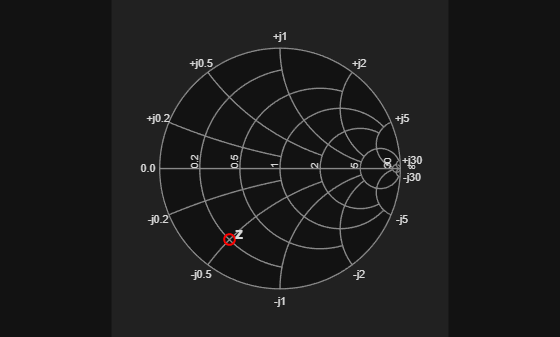

%given
ZL=15-1j*37.5;
Z0 = 75;
smithchart_plot(Z0,ZL, 'z')

## Q11 — Input Impedance with Series Capacitor and TL

% Given parameters
c0 = 2.99792458e8;          % Speed of light
f = 5e9;                    % 5 GHz
vp = 0.79 * c0;             % Phase velocity
Z0 = 60;                    % Ohm
len = 17e-3;                % 17 mm
ZL = 25 + 1j*30;            % Ohm
C = 1e-12;                  % 1 pF


r = TLine('series_C', Z0, ZL, len, C, f, vp);


   TL + SERIES CAPACITOR @ 5.00e+09 Hz
  Capacitor: 1.00 pF
  Z_C = 0.0000 -31.8310j Ohm
------------------------------------------
  Z0 = 60.00 Ohm
  ZL = 25.0000 +30.0000j Ohm
  Length = 0.3589 lambda
  Z_TL (TL input) = 21.8591 -20.0823j Ohm
------------------------------------------
  Z_A = Z_C + Z_TL
  Z_A = 21.8591 -51.9132j Ohm
  |Z_A| = 56.33 Ohm
  angle(Z_A) = -67.17 deg



% Access the answer
fprintf('Z_A = %.1f Ω ∠ %.1f°\n', abs(r.Z_A), rad2deg(angle(r.Z_A)));

Z_A = 56.3 Ω ∠ -67.2°


## Q12 — Realizing j30 Ω Using Short-Circuited TL

% Realize Z_A = j30 Ω using 75 Ω short-circuited stub
TLine('stub', 1j*30, 75, 'short')


         STUB DESIGN
  Target Z = j30.0000 Ohm
  Stub Z0 = 75.00 Ohm
------------------------------------------
  SHORT-CIRCUITED STUB:
    tan(βℓ) = 30.0000 / 75.00 = 0.400000
    βℓ = 0.3805 rad = 21.80°
    ℓ = 0.0606 λ  (or 0.5606 λ)
    Verify: Z_in = j·75.00·tan(0.3805) = j30.0000 Ohm ✓
------------------------------------------



ans = struct with fields:
      Z_target: 0.0000 +30.0000i
            Z0: 75
         short: [1×1 struct]
    len_lambda: 0.0606


## Q13 & Q14— Finding Γ_L from Γ_A

% Given: Γ_A = 0.539∠166° at plane A, Z0 = 75Ω, ℓ = 0.3λ
Gamma_A = 0.539 * exp(1j * deg2rad(166));
r = TLine('load', 75, Gamma_A, 0.3);


   FIND LOAD FROM INPUT (Q13/Q14 type)
  Z0 = 75.00 Ohm
  Gamma_in = -0.5230 +0.1304j
  |Gamma_in| = 0.5390, angle = 166.00 deg
  Length = 0.3000 lambda
------------------------------------------
  Phase shift: +2βℓ = +2·2π·0.3000 = 216.00 deg
------------------------------------------
  Gamma_L = Gamma_in · exp(+j·216.00°)
  Gamma_L = 0.4998 +0.2019j
  |Gamma_L| = 0.5390, angle = 22.00 deg
------------------------------------------
  Z_L = Z0·(1+Gamma_L)/(1-Gamma_L)
  Z_L = 182.8449 +104.0728j Ohm
  |Z_L| = 210.39 Ohm, angle = 29.65 deg
------------------------------------------
  VSWR = 3.3384



## Q15-Q17: Stub Matching

c0 = 2.998e8;
f = 1550e6;           % 1550 MHz
eps_r = 2.1;
Z0 = 75;              % Ω
ZL = 142 + 1j*42.5;   % Ω

% Q15: Calculate wavelength
lambda = c0 / (f * sqrt(eps_r));
fprintf('Q15: λ = %.2f cm\n', lambda*100);

Q15: λ = 13.35 cm



% Q16 & Q17: One command gives both answers!
StubMatch(ZL, Z0, 'short', lambda)


      SINGLE-STUB MATCHING (Q15-Q17)     
  Load: ZL = 142.00 +42.50j Ω
  Line: Z0 = 75 Ω (SHORT stub)
  λ = 13.35 cm
------------------------------------------
  SOLUTION 1:
    d = 0.1839 λ = 24.54 mm  ← Q16
    ℓ = 0.1457 λ = 19.44 mm  ← Q17
  SOLUTION 2:
    d = 0.3755 λ = 50.12 mm
    ℓ = 0.3543 λ = 47.29 mm
------------------------------------------
  ✓ Matched (y = 1.001)



ans = struct with fields:
            ZL: 1.4200e+02 + 4.2500e+01i
            Z0: 75
       Z0_stub: 75
          type: "short"
        lambda: 0.1335
             d: 0.1839
             l: 0.1457
         d_alt: 0.3755
         l_alt: 0.3543
           d_m: 0.0245
           l_m: 0.0194
          d_mm: 24.5403
          l_mm: 19.4414
          d_cm: 2.4540
          l_cm: 1.9441
      d_alt_mm: 50.1169
      l_alt_mm: 47.2866
    Y_in_check: 0.0133


## Q21

%% Q21 — Frequency of a Given Plane Wave
c0 = 2.998e8;

% From the phase term: ωt + (4y - 2x - 2z)
% β·r = -4y + 2x + 2z → β = (2, -4, 2) rad/m
beta_vec = [2; -4; 2];
beta_mag = norm(beta_vec);

fprintf('β = [%.1f, %.1f, %.1f] rad/m\n', beta_vec);

β = [2.0, -4.0, 2.0] rad/m


fprintf('|β| = √(4+16+4) = √24 = %.4f rad/m\n', beta_mag);

|β| = √(4+16+4) = √24 = 4.8990 rad/m



% In air: β = ω/c₀
omega = beta_mag * c0;
freq = omega / (2*pi);

fprintf('ω = β·c₀ = %.4e rad/s\n', omega);

ω = β·c₀ = 1.4687e+09 rad/s


fprintf('f = ω/(2π) = %.2f MHz\n', freq/1e6);

f = ω/(2π) = 233.75 MHz


## Q22-Q23 — H phasor and Poynting vector (using script)

% Given values from problem
a = [2; 1; 0];          % cos coefficient
b = [0; -1; -2];        % sin coefficient  
E0 = 10;                % V/m
beta_vec = [2; -4; 2];  % rad/m (from phase term)

% One command solves both Q22 and Q23!
r = poynting_pw('time', a, b, E0, beta_vec);


   PLANE WAVE: H-FIELD & POYNTING (Q22-Q23)
  Ẽ₀ = [20.0+0.0j; 10.0+10.0j; 0.0+20.0j] V/m
  k̂ = [0.4082, -0.8165, 0.4082]
  η = 377 Ω
------------------------------------------
  Q22: H̃₀ = (1/η)·k̂ × Ẽ₀
  H̃₀ = [-10.83-54.14j; 21.66-21.66j; 54.14+10.83j] mA/m
------------------------------------------
  Q23: S̄ = ½·Re{Ẽ × H̃*}
  S̄ = [0.541; -1.083; 0.541] W/m²
  |S̄| = 1.326 W/m²




% Access answers directly:
% Q22: r.H_phasor (in A/m, multiply by 1000 for mA/m)
% Q23: r.S_avg (in W/m²)

## Q24 — Incidence Power on Circular Surface

% Using results from Q22-Q23

% Get S_avg from poynting_pw (Q22-Q23)
a = [2; 1; 0];  b = [0; -1; -2];  E0 = 10;
beta_vec = [2; -4; 2];
r = poynting_pw('time', a, b, E0, beta_vec);


   PLANE WAVE: H-FIELD & POYNTING (Q22-Q23)
  Ẽ₀ = [20.0+0.0j; 10.0+10.0j; 0.0+20.0j] V/m
  k̂ = [0.4082, -0.8165, 0.4082]
  η = 377 Ω
------------------------------------------
  Q22: H̃₀ = (1/η)·k̂ × Ẽ₀
  H̃₀ = [-10.83-54.14j; 21.66-21.66j; 54.14+10.83j] mA/m
------------------------------------------
  Q23: S̄ = ½·Re{Ẽ × H̃*}
  S̄ = [0.541; -1.083; 0.541] W/m²
  |S̄| = 1.326 W/m²



S_avg = r.S_avg;  % [0.542; -1.083; 0.542] W/m²

% Surface parameters
D = 1;                          % Diameter [m]
A = pi * (D/2)^2;               % Area = π/4 m²
n_hat = [1; 0; 1] / sqrt(2);    % Surface normal

% Calculate incident power
S_dot_n = dot(S_avg, n_hat);
P_incident = abs(S_dot_n) * A;

fprintf('A = %.4f m²\n', A);

A = 0.7854 m²


fprintf('S̄·n̂ = %.4f W/m²\n', S_dot_n);

S̄·n̂ = 0.7657 W/m²


fprintf('P = |S̄·n̂|·A = %.3f W\n', P_incident);

P = |S̄·n̂|·A = 0.601 W


## Q25 — Skin Depth for Shielding

sigma = 58e6;       % 58 MS/m (copper)
f_max = 18e9;       % 18 GHz (worst case - smallest skin depth)

% Use Medium helper for skin depth
r = Medium('skin', sigma, f_max);


=== Skin Depth ===
  sigma = 5.800e+07 S/m
  freq = 1.800e+10 Hz
  mu_r = 1.00
  -----------------
  delta = 4.9257e-07 m
  delta = 0.4926 um
  delta = 0.0005 mm



% Rule of thumb: t_c > 5δ
t_min = 5 * r.skin_depth;
fprintf('At %.0f GHz: δ = %.3f μm\n', f_max/1e9, r.skin_depth*1e6);

At 18 GHz: δ = 0.493 μm


fprintf('Rule of thumb: t_c > 5δ = %.2f μm\n', t_min*1e6);

Rule of thumb: t_c > 5δ = 2.46 μm


## Q26 — Material Classification (Loss Tangent)

eps_r = 8;
sigma = 0.01;       % S/m
f = 5e9;            % 5 GHz

% Use Medium helper
r = Medium(eps_r, sigma, f, 1, 'Q26 Material');


  Q26 MATERIAL @ 5.00e+09 Hz
  Properties:
    eps_r = 8.0000
    mu_r  = 1.0000
    sigma = 1.000e-02 S/m
------------------------------------------
  Classification:
    tan(delta) = 4.494e-03
    Type: Lossless (approx)
------------------------------------------
  Wave Parameters:
    alpha = 6.6597e-01 Np/m
    beta  = 2.9640e+02 rad/m
    lambda = 2.1198e-02 m
    u_p = 1.0599e+08 m/s
    n = 2.8284
------------------------------------------
  Intrinsic Impedance:
    eta = 133.1933 +0.2993j Ohm
    |eta| = 133.1936 Ohm
    angle(eta) = 0.13 deg
------------------------------------------
  Attenuation:
    Skin depth = 1.5016e+00 m
    Loss @ 1m = 5.78 dB



fprintf('Classification: %s\n', r.classification);

Classification: Lossless (approx)


fprintf('tan(δ) = %.4e << 1 → Good insulator\n', r.tan_delta);

tan(δ) = 4.4938e-03 << 1 → Good insulator


## Q27 — Same material properties (wave parameters)

% Already computed above with Medium()
fprintf('From Q26 results:\n');

From Q26 results:


fprintf('  α = %.4f Np/m\n', r.alpha);

  α = 0.6660 Np/m


fprintf('  β = %.4f rad/m\n', r.beta);

  β = 296.3980 rad/m


fprintf('  λ = %.4f cm\n', r.lambda*100);

  λ = 2.1198 cm


fprintf('  η = %.2f %+.2fj Ω\n', real(r.eta), imag(r.eta));

  η = 133.19 +0.30j Ω


## Q28 — Polarization of Incident Wave


E0 = 5;  % V/m
E_phasor_Q28 = E0 * [1; sqrt(3); 2j];

% Interface is yz-plane, so wave propagates in +x direction
k_hat_Q28 = [1; 0; 0];  % Approximate (actual has y-component)

% Use Polarization helper
r = Polarization(E_phasor_Q28, k_hat_Q28);


       POLARIZATION ANALYSIS           
  Type:        Circular
  Handedness:  RHCP
----------------------------------------
  Axial Ratio: 1.1547 (1.25 dB)
  Major axis:  10.0000
  Minor axis:  8.6603
  Tilt angle:  90.00 deg
----------------------------------------
  Phasor F:
    Fx = 5.0000
    Fy = 8.6603
    Fz = j10.0000
  k_hat = [1.00, 0.00, 0.00]



fprintf('Type: %s\n', r.type);

Type: Circular


fprintf('Handedness: %s\n', r.handedness);

Handedness: RHCP


fprintf('Axial Ratio: %.2f (%.1f dB)\n', r.AR, r.AR_dB);

Axial Ratio: 1.15 (1.2 dB)


## Q29-Q30 — Angle of Incidence and Transmission


% Given β vector
beta0 = 20.94;  % rad/m
beta_Q29 = beta0 * [sqrt(3)/2; -1/2; 0];

% Interface is yz-plane, normal is x̂
n_interface = [1; 0; 0];

% Angle of incidence
cos_theta_i = dot(beta_Q29, n_interface) / norm(beta_Q29);
theta_i = acosd(cos_theta_i);
fprintf('Q29: Angle of incidence θ_i = %.1f°\n', theta_i);

Q29: Angle of incidence θ_i = 30.0°



% Snell's law for transmission angle
eps_r1 = 1;     % Air
eps_r2 = 4;     % Medium
n1 = sqrt(eps_r1);
n2 = sqrt(eps_r2);

r = Fresnel('snell', n1, n2, theta_i);


=== Snell's Law ===
  n1 = 1.0000, n2 = 2.0000
  theta_i = 30.00 deg
  theta_t = 14.48 deg



fprintf('Q30: Angle of transmission θ_t = %.1f°\n', r.theta_t);

Q30: Angle of transmission θ_t = 14.5°


## Q32 — Reflected Power Fraction (Oblique Incidence)


% Use Fresnel helper for oblique incidence
r = Fresnel(eps_r1, eps_r2, theta_i);


     FRESNEL: OBLIQUE INCIDENCE          
  Medium 1: eps_r = 1.000, n = 1.0000
  Medium 2: eps_r = 4.000, n = 2.0000
------------------------------------------
  theta_i = 30.00 deg
  theta_t = 14.48 deg (Snell's law)
  theta_Brewster = 63.43 deg
------------------------------------------
  TE (s-pol, E perpendicular to plane):
    Gamma_TE = -0.3820 +0.0000j
    |Gamma_TE| = 0.3820
    R_TE = 0.1459, T_TE = 0.8541
  TM (p-pol, E parallel to plane):
    Gamma_TM = -0.2829 +0.0000j
    |Gamma_TM| = 0.2829
    R_TM = 0.0800, T_TM = 0.9200



fprintf('Γ_TE = %.4f, R_TE = %.2f%%\n', r.Gamma_TE, r.R_TE*100);

Γ_TE = -0.3820, R_TE = 14.59%


fprintf('Γ_TM = %.4f, R_TM = %.2f%%\n', r.Gamma_TM, r.R_TM*100);

Γ_TM = -0.2829, R_TM = 8.00%


% For mixed polarization, need to weight by power in each component
% (This requires knowing the actual field decomposition)
fprintf('For mixed TE/TM, total R depends on field decomposition\n');

For mixed TE/TM, total R depends on field decomposition


## Q33 — Brewster Angle

r = Fresnel('brewster', eps_r1, eps_r2);


=== Brewster Angle ===
  n1 = 1.0000, n2 = 2.0000
  theta_B = 63.4349 deg
  At this angle: Gamma_TM = 0 (no TM reflection)



fprintf('Brewster angle θ_B = %.1f°\n', r.theta_Brewster);

Brewster angle θ_B = 63.4°


fprintf('But this wave is NOT purely TM (mixed polarization)\n');

But this wave is NOT purely TM (mixed polarization)


fprintf('→ TE component always reflects → No zero-reflection angle exists\n');

→ TE component always reflects → No zero-reflection angle exists


## Q34-Q35 — Coaxial Capacitor


a = 0.5e-2;     % Inner radius: 0.5 cm
b = 2.5e-2;     % Outer radius: 2.5 cm
L = 10e-2;      % Length: 10 cm
eps_r = 4.20;
V = 12;         % Voltage

% Capacitance of coaxial capacitor
eps = eps_r * eps0;
C = 2*pi*eps*L / log(b/a);
fprintf('Q34: Capacitance C = 2πεL/ln(b/a) = %.2f pF\n', C*1e12);

Q34: Capacitance C = 2πεL/ln(b/a) = 14.52 pF



% Energy stored
W = 0.5 * C * V^2;
fprintf('Q35: Energy W = ½CV² = %.1f pJ\n', W*1e12);

Q35: Energy W = ½CV² = 1045.3 pJ


## Q36-Q37 — Solenoid current and inductance


N = 200;            % Number of turns
L_sol = 10e-2;      % Length: 10 cm
d = 1.3e-2;         % Diameter: 1.3 cm
B = 6.28e-3;        % Measured B: 6.28 mT

% Q36: Current from B = μ₀·n·I
n = N / L_sol;      % Turns per meter
I = B / (mu0 * n);
fprintf('Q36: Current I = B/(μ₀n) = %.2f A\n', I);

Q36: Current I = B/(μ₀n) = 2.50 A


% Q37: Inductance L = μ₀·N²·A/ℓ
A_sol = pi * (d/2)^2;
L_ind = mu0 * N^2 * A_sol / L_sol;
fprintf('Q37: Inductance L = μ₀N²A/ℓ = %.2f μH\n', L_ind*1e6);

Q37: Inductance L = μ₀N²A/ℓ = 66.72 μH


## SUMMARY - Function Usage Reference

fprintf('Medium(eps_r, freq)              - Lossless dielectric\n');

Medium(eps_r, freq)              - Lossless dielectric


fprintf('Medium(eps_r, sigma, freq)       - Lossy medium\n');

Medium(eps_r, sigma, freq)       - Lossy medium


fprintf('Medium(''conductor'', sigma, freq) - Good conductor\n');

Medium('conductor', sigma, freq) - Good conductor


fprintf('Medium(''skin'', sigma, freq)      - Skin depth only\n');

Medium('skin', sigma, freq)      - Skin depth only


fprintf('\n');
fprintf('TLine(Z0, ZL, len_lambda)        - Full TL analysis\n');

TLine(Z0, ZL, len_lambda)        - Full TL analysis


fprintf('TLine(''Gamma'', Z0, Z)            - Γ from impedance\n');

TLine('Gamma', Z0, Z)            - Γ from impedance


fprintf('TLine(''Z'', Z0, Gamma)            - Z from Γ\n');

TLine('Z', Z0, Gamma)            - Z from Γ


fprintf('TLine(''Zin'', Z0, ZL, len)        - Input impedance\n');

TLine('Zin', Z0, ZL, len)        - Input impedance


fprintf('TLine(''QW'', Zs, ZL)              - Quarter-wave design\n');

TLine('QW', Zs, ZL)              - Quarter-wave design


fprintf('\n');
fprintf('StubMatch(ZL, Z0, ''short'')       - Short stub matching\n');

StubMatch(ZL, Z0, 'short')       - Short stub matching


fprintf('StubMatch(ZL, Z0, ''open'')        - Open stub matching\n');

StubMatch(ZL, Z0, 'open')        - Open stub matching


fprintf('\n');
fprintf('Polarization(F_phasor)           - Analyze polarization\n');

Polarization(F_phasor)           - Analyze polarization


fprintf('Polarization(F, k_hat)           - With propagation dir\n');

Polarization(F, k_hat)           - With propagation dir


fprintf('Polarization(''ap'', Ex, Ey, φx, φy) - Amplitude/phase\n');

Polarization('ap', Ex, Ey, φx, φy) - Amplitude/phase


fprintf('\n');
fprintf('Fresnel(eps1, eps2)              - Normal incidence\n');

Fresnel(eps1, eps2)              - Normal incidence


fprintf('Fresnel(eps1, eps2, theta)       - Oblique incidence\n');

Fresnel(eps1, eps2, theta)       - Oblique incidence


fprintf('Fresnel(''brewster'', eps1, eps2)  - Brewster angle\n');

Fresnel('brewster', eps1, eps2)  - Brewster angle


fprintf('Fresnel(''critical'', eps1, eps2)  - Critical angle\n');

Fresnel('critical', eps1, eps2)  - Critical angle


fprintf('Fresnel(''snell'', n1, n2, theta)  - Transmission angle\n');

Fresnel('snell', n1, n2, theta)  - Transmission angle
